# **Trapezoidal Rule** 

The trapezoidal rule is the first of the Newton-Cotes closed integration formulas. It corresponds to the case where the polynomial is first order 


$$I=\int_a^b f\left(x\right)\textrm{dx}\cong \int_a^b f_1 \left(x\right)\textrm{dx}$$


the result of this integration is 


$$I=\left(b-a\right)\frac{f\left(a\right)+f\left(b\right)}{2}$$


### 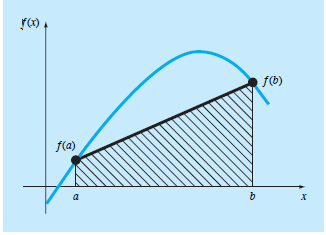

### `The Multiple-Application Trapezoidal Rule`

One way to improve the accuracy of the trapezoidal rule is to divide the integration interval from a to b into a number of segments and apply the method to each segment

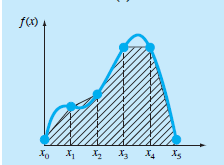

There are n + 1 equally spaced base points (x0, x1, x2, . . . ,xn). Consequently, there are n segments of equal width:

*h* = $\frac{b-a}{n}$

The final integrating value 

### 
$$I=\frac{h}{2}\left\lbrack f\left(x_0 \right)+2\sum_{i=1}^{n-1} f\left(x_i \right)+f\left(x_n \right)\right\rbrack$$


### **Step 1 : Defining the Function **

First step of trapezoidal rule is to define the function and it's lower bound and upper bound which is **a** and **b** . Then we have to define the number of sagments **n**. 

For defining the function we have used inline function from matlab.In **input **we have given two parameter .1st parameter is **prompt** and the 2nd one indicates that the input is a **string.**Then using inline we have converted the string to a function.

f_input =input("Enter your function : ","s") ;           %Function of variable x
f = inline(f_input)  ;                                   %Using inline function
a = input ( "Value of a =");
b = input ( "Value of b =");
n = input ( "Value of n =");

### **Step 2 : Finding Step size**

We will divide the difference between upperbound and lowerbound into n sections and we called this **h** .This value is called step size .We have to find the functional value starting from lower bound and evrey time it will increase the amount of step size upto upper bound 

h = ( b-a) / n ;

### **Step 3 :Calculating the sum of initial and final boundary value of Function**

From the final trapezoidal rule we can see there is no co-efficient in the functional  extreme boundary value. So we will sum up two extreme functional value and called it **s**

s = f(a) + f (b);

### **Step 4 : Declaring the  sum value of middle points **

We have to sum up all the middelpoint functional value and multiply it by 2 . So we declare variable as s_middle and sets it's initial value 0

 s_middle = 0 ;

### **Step 5 : Calculating the total  sum value of middle points(s_middle)** 

In this step we will calculate the final vale of s_middle. Our middle points will start from from 1 and increase by 1 upto the previous value of upperbound. We will use for loop to generate those middle values. Inside the for loop we will calculate the functional value of those particular point and multilpy it by 2, named this as temp_values.After that we will calculate the latest s_middle by adding temp_values with previous temp_values and end our for loop.

for i = 1 : 1 : n-1 
     temp_values = 2* f (a + i*h); 
     s_middle = s_middle + temp_values;
     
end 

### **Step 6 : Final intigration value using trapezoidal rule**

As we have calculated the sum of boundary values ,all middle functional values multiplying by 2 , we will add all those values and multiply it by $\frac{b-a}{2n}$.Finally we will print the the integration value using **frpintf** function.

Intigration_value = ((b-a)/(2*n)) * ( s+s_middle) ;
fprintf("The Value of integration using Trapezoidal Rule is % f",Intigration_value);